# Goertzel Algorithm

The **Goertzel algorithm** is a technique in [digital signal processing](https://en.wikipedia.org/wiki/Digital_signal_processing) (DSP) that provides a means for efficient evaluation of individual terms of the [discrete Fourier transform](https://en.wikipedia.org/wiki/Discrete_Fourier_transform) (DFT), thus making it useful in certain practical applications, such as recognition of [DTMF](https://en.wikipedia.org/wiki/Dual-tone_multi-frequency_signaling) tones produced by the buttons pushed on a telephone keypad. The algorithm was first described by [Gerald Goertzel](https://en.wikipedia.org/wiki/Gerald_Goertzel) in 1958.

`dft_data = goertzel(data)` returns the discrete Fourier transform (DFT) of the input data, `data`, using a second-order Goertzel algorithm. If `data` is a matrix, `goertzel` computes the DFT of each column separately.

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
samplingFrequency = 48000;             % 48 KHz
f0 = 20e+3;                            % 20 KHz
f1 = 10e+3;                            % 10 KHz
duration = (127/samplingFrequency);    % ~ 2.6 ms 
t = 0:1/samplingFrequency:duration;    % Time Vector

sinusPulse = Am*sin(2*pi*f0*t) + Am/2*sin(2*pi*f1*t);   % Signal with two frequencies 
noisySinus_3dB = awgn(sinusPulse,3);       % Add noise to sinusPulse with SNR = 3 dB

f = 0:5e+3:samplingFrequency;       % f vector
freqIndices = round(f/samplingFrequency*length(sinusPulse)) + 1;

Applying *Goeortzel Algorithm *in scrutation mode which means 100 time for 1 value of SNR for asserting the detection of the frequencies.

For that we create two variables detectF0 and detectF1 to store how many times the goertzel algorithm detects these frequencies, by comparing their Magnitude values with thresholds.

detectF0 = 0;           % Counter stores detection of f0 
detectF1 = 0;           % Counter stores detection of f1
for i=1:100
    dft_goertzel = abs(goertzel(noisySinus_3dB,freqIndices));   % Apply Goertzel function
    if dft_goertzel(3) > 20             % Random threshold
        detectF0 = detectF0 + 1;
    end
    if dft_goertzel(5) > 50             % Random Threshold
        detectF1 = detectF1 + 1;
    end
end

Plotting the DFT(Discrete Fourier Transform) Magnitude.

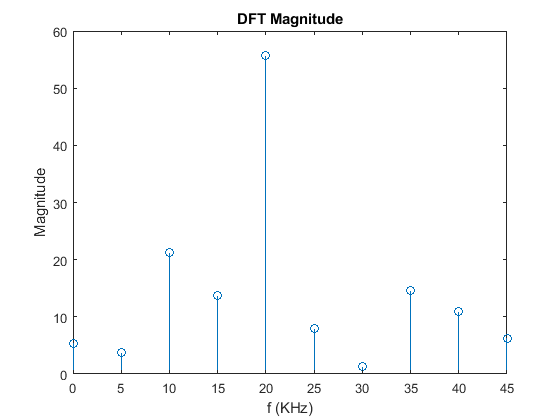

stem(f/1e3,dft_goertzel)
ax = gca;
ax.XTick = f/1e3;
xlabel('f (KHz)')
title('DFT Magnitude')
ylabel('Magnitude')

Displaying the Probabilities of detction for each frequency.

Pd_3 = detectF0/100

Pd_3 = 1

Pd_5 = detectF1/100

Pd_5 = 1

As a conclusion we figured out that the probability of detection increases by decreasing the SNR values and vice-versa. 

#### Referencees :

- [https://web.archive.org/web/20180628024641/http://en.dsplib.org/content/goertzel/goertzel.html](https://web.archive.org/web/20180628024641/http://en.dsplib.org/content/goertzel/goertzel.html)

        Goertzel 

- [https://www.mathworks.com/help/signal/ref/goertzel.html](https://www.mathworks.com/help/signal/ref/goertzel.html)

        DFT Estimation with the Goertzel Algorithm

- [https://www.mathworks.com/help/signal/examples/dft-estimation-with-the-goertzel-algorithm.html](https://www.mathworks.com/help/signal/examples/dft-estimation-with-the-goertzel-algorithm.html)